# Script 6: Weather Data Cleaning

This script focuses on getting the raw data aggregated in Script5 into a clean, useable form.

## Load aggregated weather data

load('weather_original')
head(weatherDataUnstack)

ans = 8×18 table
            Date               KBGM          KISP          KSWF          KLGA          KBUF          KALB          KELM          KPOU          KROC          KSYR          KMSV          KRME          KPBG          KHPN          KMSS          KJFK          KART   
    ____________________    __________    __________    __________    __________    __________    __________    __________    __________    __________    __________    __________    __________ 

## Align the data points on the hour using `timetable` and `retime`

Since the times each weather station reports data at is not the same, when we unstack the table they don't line up at the same time. We are left with a very sparse, irregularly spaced table mostly filled with `NaN'`s. We can use `timetable` to move everything onto the hour. A `timetable` is like a regular table but each row must be associated with a timestamp.

% convert the table into a timetable
weatherDataTT = table2timetable(weatherDataUnstack);
% use the retime function to move the data by using a linear interpolant
% options include 'mean', 'nearest', 'linear', 'spline', 'pchip' among others
weatherDataRetimed = retime(weatherDataTT, 'hourly', 'mean');
% the results are now on the hour
weatherDataRetimed(1:8, :)

ans = 8×17 timetable
            Date              KBGM        KISP         KSWF         KLGA        KBUF        KALB        KELM        KPOU        KROC        KSYR        KMSV         KRME          KPBG         KHPN        KMSS        KJFK        KART  
    ____________________    ________    ________    __________    ________    ________    ________    ________    ________    ________    ________    ________    __________    __________    __

## Take a look at some of the temperature readings

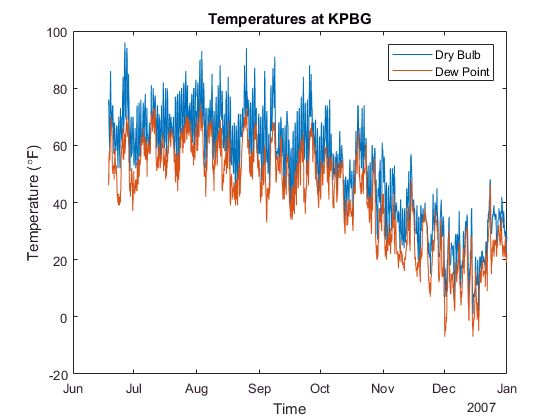

stationName = 'KPBG';
plot(weatherDataRetimed.Date,weatherDataRetimed.(stationName))
xlabel('Time')
ylabel('Temperature (\circF)')
title(['Temperatures at ' stationName])
legend('Dry Bulb','Dew Point')

## Find missing values

Some hours had no reported data and are missing in the retimed table. We can use `ismissing` to find any missing values and plot the location of missing values by weather station using a local function.

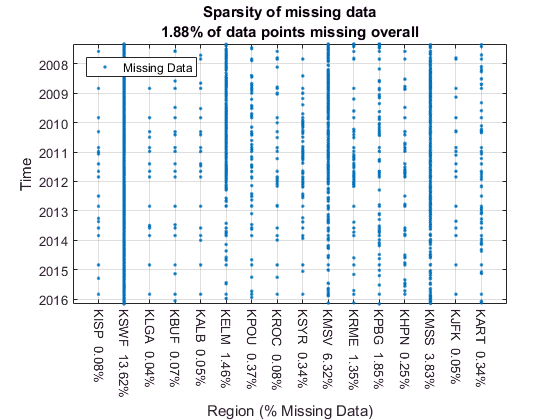

% idxmissing can find which entries are missing
idxmissing = ismissing(weatherDataRetimed);
% this local function will plot the sparsity of the missing data
% each dot is a point where we are missing data
dataSparsityPlot(weatherDataRetimed)

## Fill in missing values

Some of the weather stations have a large number of small gaps. One way to handle this is to use `fillmissing` to interpolate the missing values. However since this goes column by column, we don't want to extrapolate the end values. Two weather stations, KRME and KPBG, will still be missing some data points at the beginning due to this.

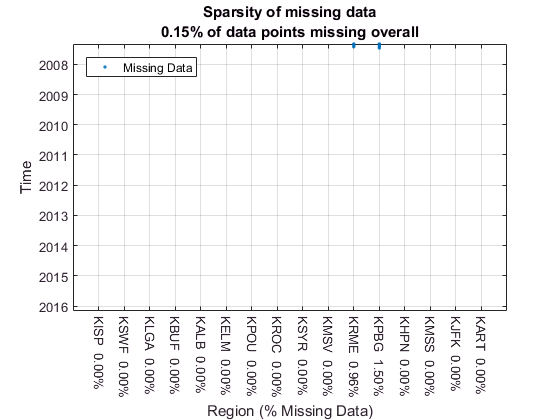

% use fillmissing to fill in missing sections, while not extrapolating
weatherDataFilled = fillmissing(weatherDataRetimed, 'pchip', 'EndValues', 'none');
% recreate sparsity plot now that we have filled in values
dataSparsityPlot(weatherDataFilled)

## Where are the weather stations?

Let's plot them on a map to see where they are. 

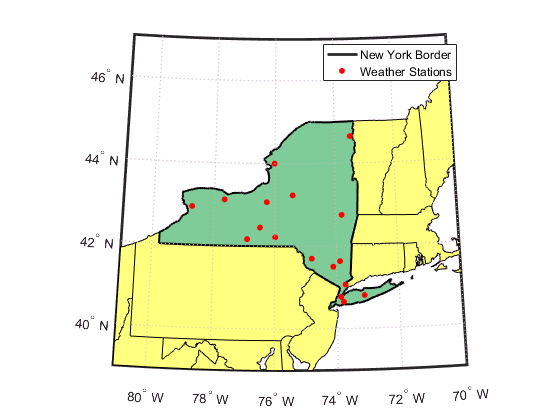

% load in station lat/lon coordinates
load('stnlatlon')
idxMissingStn = stnlatlon.Name=='KRME' | stnlatlon.Name=='KPBG';
% load in geographic information
states = geoshape(shaperead('usastatehi', 'UseGeoCoords', true));
ny = states(strcmp(states.Name, 'New York'));
% plot station locations
figure
ax = usamap('ny');
geoshow(states)
nyline = geoshow(ny, 'LineWidth', 1.5, 'FaceColor', [.5 .8 .6]);
activePoints = geoshow(stnlatlon.LAT,stnlatlon.LON,...
        'DisplayType', 'point','Marker', 'o','MarkerEdgeColor', 'r',...
        'MarkerFaceColor', 'r','MarkerSize', 4);
legend('New York Border','Weather Stations')

## Interpolate missing values geographically

An alternative to `fillmissing`, which isolates each column, is to interpolate the missing values based on the weather stations around them. Using the station latitude, longitude and timestamp at each point, we can use a `scatteredInterpolant` to interpolate based on the data we have using the form $\textrm{Temperature}=F\left(\textrm{Latitude},\textrm{Longitude},\textrm{Time}\right)$. In order to interpolate, the station must be within the convex hull of the data points that we have. If they are not we can still extrapolate, however the results may be poor.

% using smaller subset will dramatically speed up execution of the scatteredInterpolant command

% idxMap = weatherDataRetimed.Date >= datetime('Aug 24, 2010','TimeZone','America/New_York') & ...
%     weatherDataRetimed.Date <= datetime('Aug 31, 2011','TimeZone','America/New_York');
idxMap = weatherDataRetimed.Date < datetime('Jan 1, 2019','TimeZone','America/New_York');

% restack to get data in format for scatteredInterpolant
weatherDataMap = stack(weatherDataRetimed(idxMap,:),weatherDataRetimed.Properties.VariableNames,...
    'NewDataVariableName','Temp','IndexVariableName','Station');

% Need to convert back to table first to join with stnlatlon table
weatherDataMap = timetable2table(weatherDataMap);
    
% join the new table with the latitude and longtiude data
weatherDataMapJoined = innerjoin(weatherDataMap,stnlatlon,'LeftKey','Station','RightKey','Name');

% find the missing values 
idxnan1 = isnan(weatherDataMapJoined.Temp(:,1));
idxnan2 = isnan(weatherDataMapJoined.Temp(:,2));

% Due to time and temperature being measured in different units, we will scale
% the time measurements to put them on more equal ground. There are more robust
% ways to do this, but it will work for our purposes.
timeMod = 24;
interpTime = datenum(weatherDataMapJoined.Date)*timeMod;

% create the scattered interpolants based on data we do have
% make a separate one for dry bulb and dew point temperatures
dryBulbFcn = scatteredInterpolant(weatherDataMapJoined.LAT(~idxnan1),weatherDataMapJoined.LON(~idxnan1),...
    interpTime(~idxnan1),weatherDataMapJoined.Temp(~idxnan1,1));
dewPntFcn = scatteredInterpolant(weatherDataMapJoined.LAT(~idxnan2),weatherDataMapJoined.LON(~idxnan2),...
    interpTime(~idxnan2),weatherDataMapJoined.Temp(~idxnan2,2));

% interpolate/extrapolate the values for temperature
weatherDataMapJoined.Temp(idxnan1,1) = dryBulbFcn(weatherDataMapJoined.LAT(idxnan1),weatherDataMapJoined.LON(idxnan1),...
    interpTime(idxnan1));
weatherDataMapJoined.Temp(idxnan2,2) = dewPntFcn(weatherDataMapJoined.LAT(idxnan2),weatherDataMapJoined.LON(idxnan2),...
    interpTime(idxnan2));
% unstack the results for easier handling
weatherDataMapFilled = unstack(weatherDataMapJoined(:,{'Date','Temp','Station'}),'Temp','Station');

Let's visualize how the interpolation does on one of the missing areas. Below are the values for the KSWF station after interpolation with the missing values highlighted.

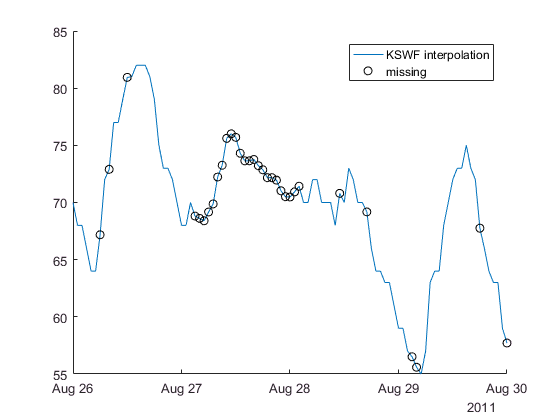

station = 'KSWF';
idxm = isnan(weatherDataRetimed{idxMap,station});
figure;hold on
plot(weatherDataMapFilled.Date,weatherDataMapFilled.(station)(:,1))
plot(weatherDataMapFilled.Date(idxm(:,1)),weatherDataMapFilled.(station)(idxm(:,1),1),'ko')
hold off
xlim([datetime('Aug 26, 2011','TimeZone','America/New_York'),datetime('Aug 30, 2011','TimeZone','America/New_York')])
legend([station ' interpolation'],'missing')

## Visualize `scatteredInte``rpolant` results for KRME

First let's look at the KRME weather station. We can interpolate the results because the missing values are within the convex hull of the data points that we have. 

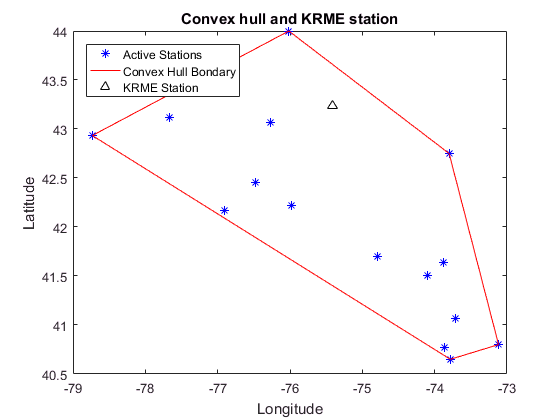

KRMEconvhull = convhull(stnlatlon.LON(~idxMissingStn),stnlatlon.LAT(~idxMissingStn));
hullPoints = [stnlatlon(~idxMissingStn,:).LON(KRMEconvhull),stnlatlon(~idxMissingStn,:).LAT(KRMEconvhull)];
figure
plot(stnlatlon.LON(~idxMissingStn),stnlatlon.LAT(~idxMissingStn),'b*',...
    hullPoints(:,1),hullPoints(:,2),'-r',...
    stnlatlon{stnlatlon.Name=='KRME','LON'},stnlatlon{stnlatlon.Name=='KRME','LAT'},'k^')
legend('Active Stations','Convex Hull Bondary','KRME Station','Location','northwest')
xlabel('Longitude')
ylabel('Latitude')
title('Convex hull and KRME station')

And if we look at a plot of the interpolated results (first month of data) they look reasonable.

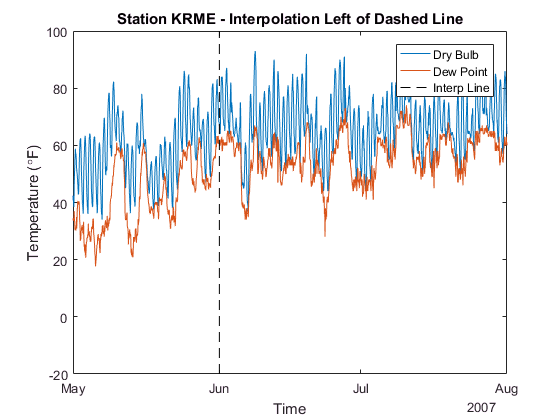

% plot temperature data
plot(weatherDataMapFilled.Date,weatherDataMapFilled.KRME)
% add interpolation cutoff point
idxKRMEmissing = isnan(weatherDataRetimed.KRME);
rKRMEmissing = find(~idxKRMEmissing(:,1));
hold on
plot(repmat(weatherDataRetimed.Date(rKRMEmissing(1))+minutes(30),1,2),[-20,100],'--k')
% plot customizations
xlim([datetime('May 1, 2007','TimeZone','America/New_York'),datetime('Aug 1, 2007','TimeZone','America/New_York')])
xlabel('Time')
ylabel('Temperature (\circF)')
title('Station KRME - Interpolation Left of Dashed Line')
legend('Dry Bulb','Dew Point','Interp Line')

## Visualize `scatteredInte``rpolant` results for KPBG

The KPBG station on the other hand is not contained within the convex hull.

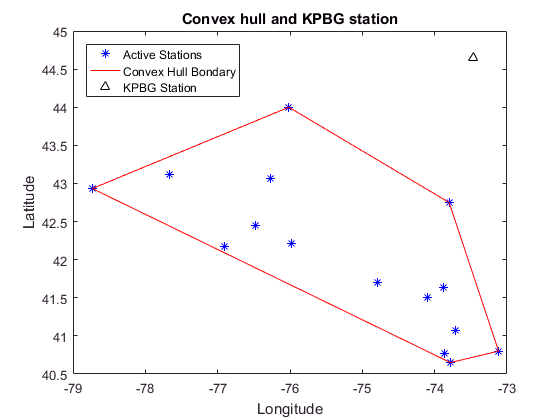

KPBGconvhull = convhull(stnlatlon.LON(~idxMissingStn),stnlatlon.LAT(~idxMissingStn));
hullPoints = [stnlatlon(~idxMissingStn,:).LON(KPBGconvhull),stnlatlon(~idxMissingStn,:).LAT(KPBGconvhull)];
figure
plot(stnlatlon.LON(~idxMissingStn),stnlatlon.LAT(~idxMissingStn),'b*',...
    hullPoints(:,1),hullPoints(:,2),'-r',...
    stnlatlon{stnlatlon.Name=='KPBG','LON'},stnlatlon{stnlatlon.Name=='KPBG','LAT'},'k^')
legend('Active Stations','Convex Hull Bondary','KPBG Station','Location','northwest')
xlabel('Longitude')
ylabel('Latitude')
title('Convex hull and KPBG station')

This means we must perform extrapolation, for which there are only simple methods which clearly do not do well (see first month of data). To fill this in more accurately, we would need to turn to more sophisticated techniques like machine learning or first principles modeling.

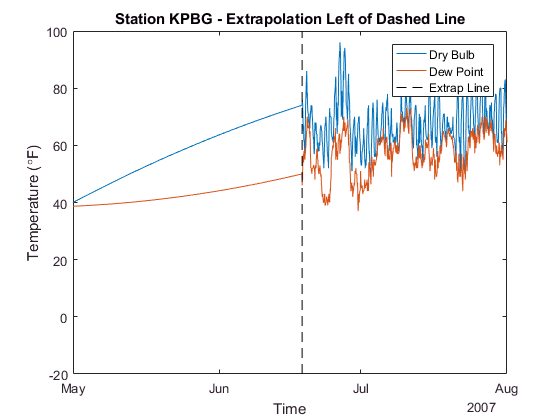

plot(weatherDataMapFilled.Date, weatherDataMapFilled.KPBG)
idxKPBGmissing = isnan(weatherDataRetimed.KPBG);
rKPBGmissing = find(~idxKPBGmissing(:, 1));
hold on
plot(repmat(weatherDataRetimed.Date(rKPBGmissing(1))+minutes(30),1,2),[-20,100],'--k')
xlim([datetime('May 1, 2007','TimeZone','America/New_York'), datetime('Aug 1, 2007','TimeZone','America/New_York')])
xlabel('Time')
ylabel('Temperature (\circF)')
title('Station KPBG - Extrapolation Left of Dashed Line')
legend('Dry Bulb', 'Dew Point', 'Extrap Line')

## Save weather data for later use

It looks like the KRME data interpolation may be good enough to use, but the KPBG data needs to be left blank. Let's save the cleaned up weather data for later use.

weatherData = table2timetable(weatherDataMapFilled);
weatherData.KPBG(isnan(weatherDataFilled.KPBG)) = NaN;
if false
    save(fullfile(prj.RootFolder, "SavedData", "weather_cleaned.mat"), "weatherData") %#ok<UNRCH> 
end

*Copyright 2014-2018 The MathWorks, Inc.*